The Statistics and Machine Learning Toolbox is required for defining the densities:

[Statistics and Machine Learning Toolbox](matlab:matlab.internal.addons.launchers.showExplorer('ErrorRecovery', 'identifier', 'ST', 'focused', 'lognpdf');).

**Defining a few different distributions:**

mu_lognormal = 0; % Mean of the log of the variable
sigma_lognormal = 1; % Standard deviation of the log of the variable
f_lognormal = @(x) lognpdf(x, mu_lognormal, sigma_lognormal);

alpha_pareto = 2; % Shape parameter
xm_pareto = 1; % Scale parameter
f_pareto = @(x) gampdf(x, alpha_pareto, xm_pareto);

a_gamma = 2; % Shape parameter
b_gamma = 1; % Scale parameter
f_gamma = @(x) gampdf(x, a_gamma, b_gamma);

mu_invgauss = 1; % Mean parameter
lambda_invgauss = 3; % Scale parameter
pd_invgauss = makedist('InverseGaussian', 'mu', ...
mu_invgauss, 'lambda', lambda_invgauss);
f_invgauss = @(x) pdf(pd_invgauss, x);

% Example: Evaluate the density functions at x = 2
x = 10;
density_lognormal = f_lognormal(x);
density_pareto = f_pareto(x);
density_gamma = f_gamma(x);
density_invgauss = f_invgauss(x);

**Example usage:**

K = 2;
n = 100;
s_values = [1, 5, 10];

[A, b, p, x_values] = produce_Laplace_data(f_pareto, K, s_values, n)

A =     0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100    0.0100
         0    0.0022    0.0043    0.0065    0.0087    0.0109    0.0130    0.0152    0.0174    0.0195    0.0217    0.0239    0.0260    0.0282    0.0304    0.0326    0.0347    0.0369    0.0391    0.0412    0.0434    0.0456    0.0478    0.0499    0.0521    0.0543    0.0564    0.0586    0.0608    0.0629    0.0651    0.0673    0.0695    0.0716    0.0738    0.0760    0.0781    0.0803    0.0825    0.0847    0.0868    0.0890    0.0912    0.0933    0.0955    0.0977    0.0998    0.1020    0.1042    0

b =     0.0459
    0.0921
    0.2764
    0.0113
    0.0011
    0.0002


p =          0    0.1747    0.2812    0.3395    0.3644    0.3666    0.3541    0.3325    0.3059    0.2770    0.2477    0.2193    0.1926    0.1679    0.1455    0.1255    0.1078    0.0922    0.0785    0.0667    0.0565    0.0478    0.0403    0.0339    0.0285    0.0239    0.0200    0.0167    0.0139    0.0116    0.0097    0.0080    0.0067    0.0056    0.0046    0.0038    0.0032    0.0026    0.0022    0.0018    0.0015    0.0012    0.0010    0.0008    0.0007    0.0006    0.0005    0.0004    0.0003    0.0003


x_values =          0    0.2171    0.4341    0.6512    0.8682    1.0853    1.3023    1.5194    1.7364    1.9535    2.1705    2.3876    2.6046    2.8217    3.0387    3.2558    3.4728    3.6899    3.9069    4.1240    4.3410    4.5581    4.7752    4.9922    5.2093    5.4263    5.6434    5.8604    6.0775    6.2945    6.5116    6.7286    6.9457    7.1627    7.3798    7.5968    7.8139    8.0309    8.2480    8.4650    8.6821    8.8991    9.1162    9.3333    9.5503    9.7674    9.9844   10.2015   10.4185   10.6356


**Visualising p:**

figure; 
plot(x_values, p, '-o'); 
xlabel('x values'); 
ylabel('Density p'); 
title('Discretized Pareto Density'); 
grid on; 

## Data from the paper

In the paper "A Maximum Entropy Method for Inverting Laplace Transforms of Probability Density Functions", the other indicate the coefficient of variation g that they use for different distributions. They show graphical results for g=0.8 and give tabled residuals for g=0.2, 0.4, 0.6, 0.8, 1.0, 1.2, and 1.4.

**Data for Gamma distribution with g=0.8 (Fig 1., page 890)**

Gamma distribution has mean a / b and stddev sqrt(a) / b, therefore g = 1 / sqrt(a). So g = 0.8 implies a = 1.5625

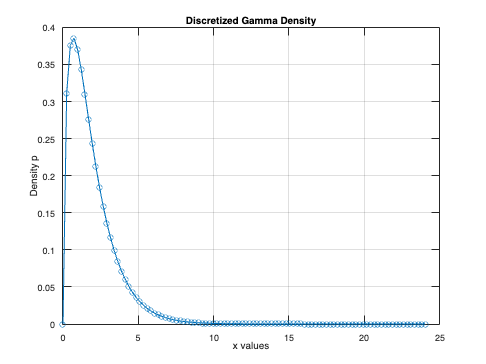

a_gamma = 1.5625; % Shape parameter
b_gamma = 1.2; % Scale parameter
f_gamma = @(x) gampdf(x, a_gamma, b_gamma);
K = 2;
n = 100;
s_values = [1, 5, 10];

% mean = a/ b
% var = a / b^2

[A, b, p, x_values] = produce_Laplace_data(f_gamma, K, s_values, n);

figure; 
plot(x_values, p, '-o'); 
xlabel('x values'); 
ylabel('Density p'); 
title('Discretized Gamma Density'); 
grid on; 

**Data for Pareto distribution with g=0.8 (Fig 2., page 890)**

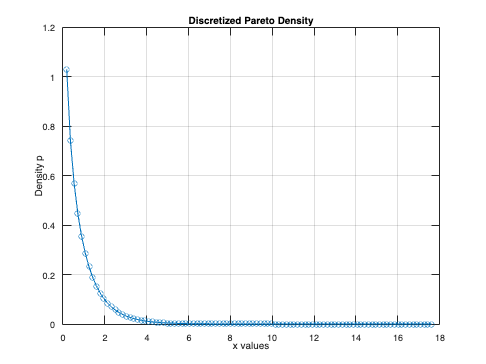

alpha_pareto = 0.78; % Shape parameter
xm_pareto = 1; % Scale parameter
f_pareto = @(x) gampdf(x, alpha_pareto, xm_pareto);
K = 2;
n = 100;
s_values = [1, 5, 10];

% mean = a/ b
% var = a / b^2

[A, b, p, x_values] = produce_Laplace_data(f_pareto, K, s_values, n);

figure; 
plot(x_values, p, '-o'); 
xlabel('x values'); 
ylabel('Density p'); 
title('Discretized Pareto Density'); 
grid on; 